# In-Class Problems for Lecture 6: MATLAB Basics

Use MATLAB for this set of problems.

## Problem 1

We will start from a basic MATLAB script to add some desired components. This script is available in the [checlassfa20 git repository](https://bitbucket.org/ashleefv/checlassfa20/src/master/In%20Class%20Problem%20Activities/MATLAB/MATLABBasicsStart.m). To run the codes in this MATLAB live script press Ctrl + Enter.

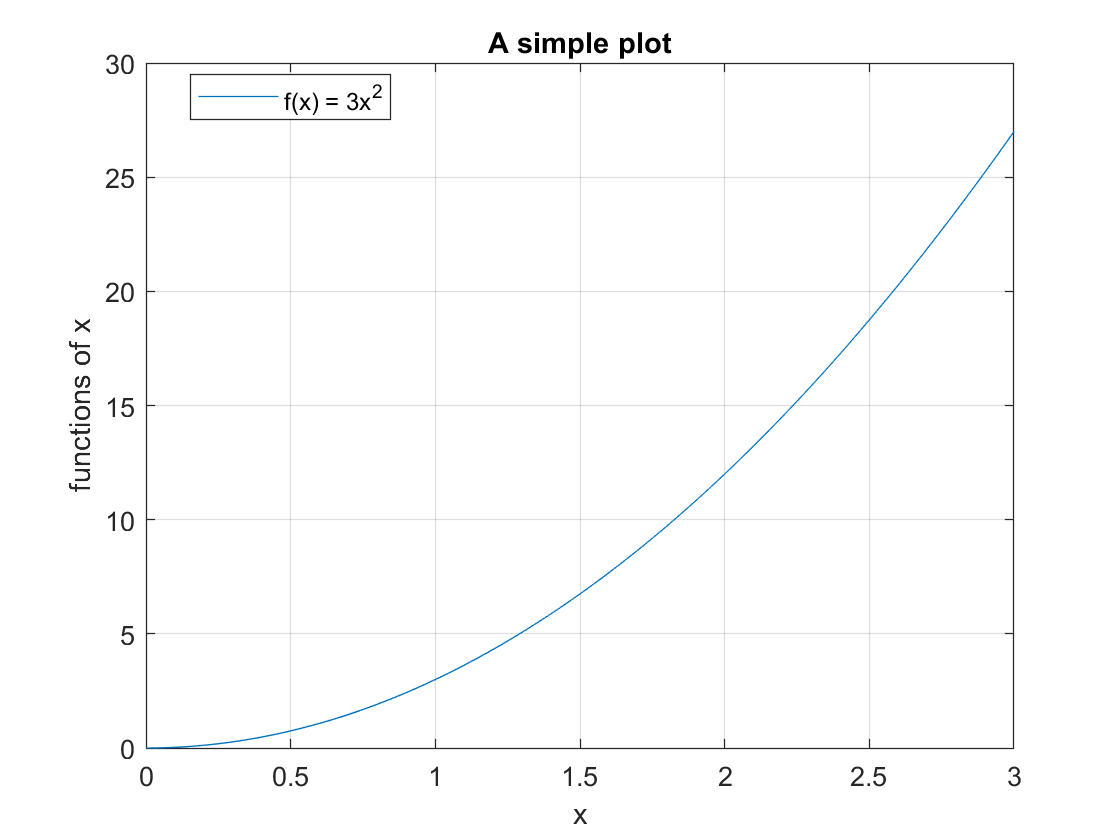

%% MATLABBasicsStart.m
%   make a very simple plot of one function.

%% set parameters
xmin=0;
xmax=3;
Nx=200;

%% set independent variable
x=linspace(xmin,xmax,Nx);

%% calculate function values
f = 3*x.^2;

%% plot results
plot(x,f)
xlabel('x')
ylabel('functions of x')
legend('f(x) = 3x^2','Location','Best');
title('A simple plot')
grid on

Edit the MATLAB code below to do the following:

- Calculate a second expression: $g(x) = x$

- Suppress printing of this expression

- Plot $g(x)$ on the same figure as$f(x)$

- Label both $f(x)$and $g(x)$using a legend

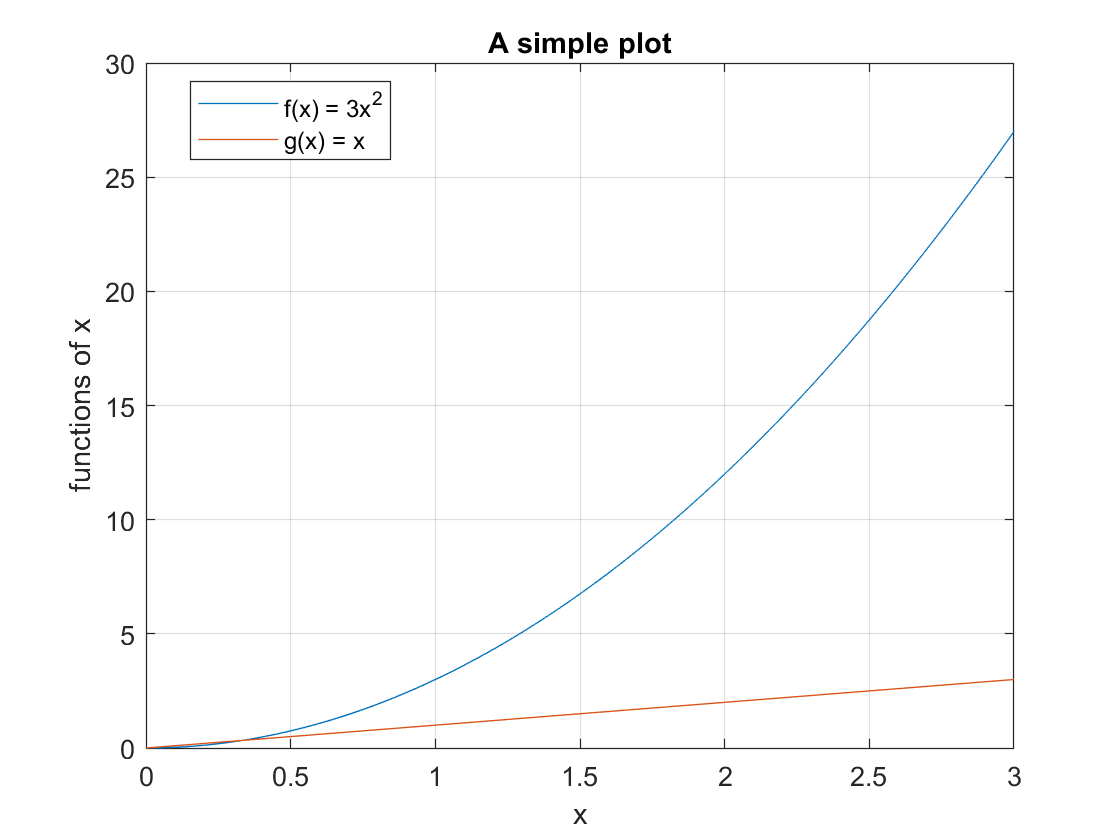

%% MATLABBasicsStart.m
%   make a very simple plot of one function.

%% set parameters
xmin=0;
xmax=3;
Nx=200;

%% set independent variable
x=linspace(xmin,xmax,Nx);

%% calculate function values
f = 3*x.^2;
%% plot results
plot(x,f)
xlabel('x')
ylabel('functions of x')
legend('f(x) = 3x^2','Location','Best');
title('A simple plot')
grid on

# Problem 2

Copy and paste the code you developed in Problem 1 at the bottom of this document, and make it into a function named MATLABBasics.m.

Allow the three parameters xmin, xmax, and Nx to be the inputs to the function, in this order.

No output is needed.

Confirm that the new function still works and can accept input 

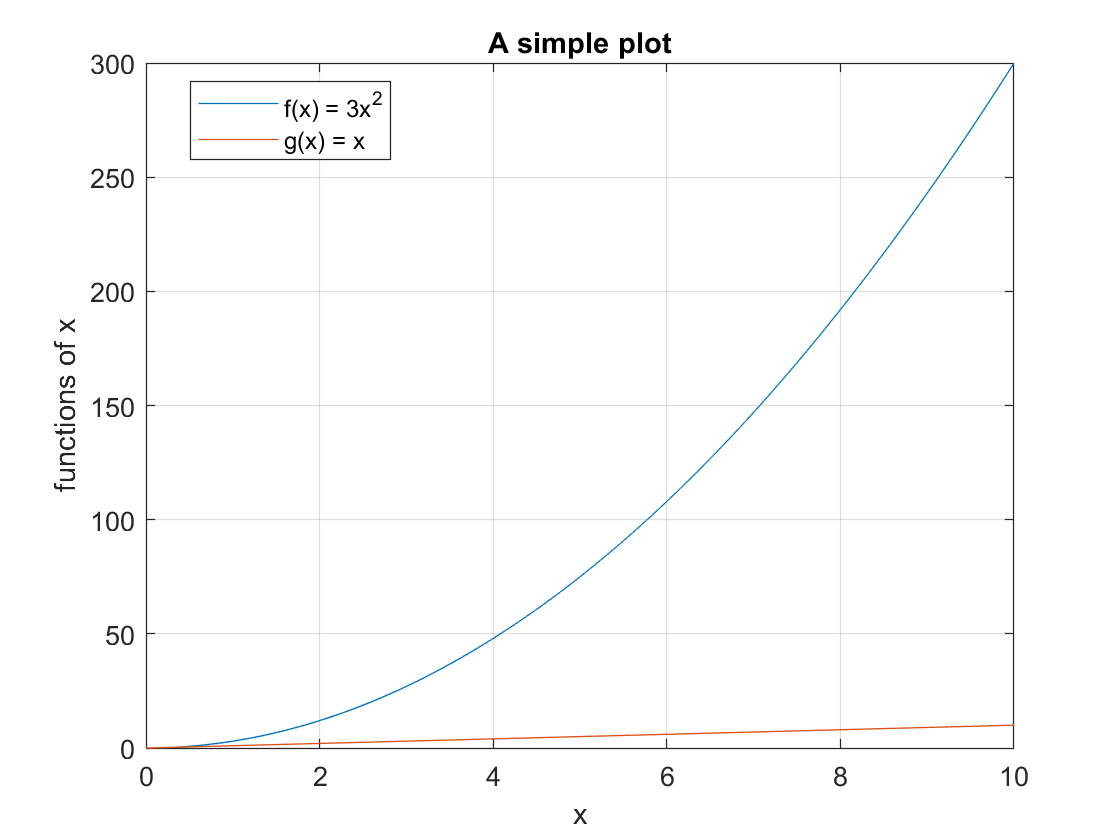

MATLABBasics(0,10,200)

This should work. 

MATLABBasics()

This should fail, because we've defined a function that must have three inputs. Without three inputs, the function doesn't know what to do for the missing values.

Next modify your function MATLABBasics code to accept a variable number of arguments using the keyword **varargin**. Set the default values to 

xmin=0; xmax=3; Nx=200

Nx = 200

For example, use the following code snippet to check to see if xmin is given or not and either use varargin{1} where 1 denotes the 1st input or use the default if the value is not given:

if nargin < 1

	xmin = 0;

else

	xmin = varargin{1};	

end

To test your new function, try running 

MATLABBasics()

If it doesn't work, did you make an if statement for each input? You should get the same plot for both commands.

## Code for your new function MATLABBasics

%% MATLABBasics.m
%   make a very simple plot of one function.

